[fecg1DIR, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_fecg1',1);
[fecg2DIR, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_fecg1',2);
[fecg3DIR, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_fecg1',3);
[fecg4DIR, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_fecg1',4);

[mecg1, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_mecg',1);
[mecg2, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_mecg',2);
[mecg3, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_mecg',3);
[mecg4, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_mecg',4);

[noise11, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_noise1',1);
[noise12, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_noise1',2);
[noise13, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_noise1',3);
[noise14, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_noise1',4);

[noise21, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_noise2',1);
[noise22, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_noise2',2);
[noise23, ~, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_noise2',3);
[noise24, fs, ~] = rdsamp('testSynthDB/sub05_snr06dB_l1_c0_noise2',4);


[time, m, atrtimed, annotd] = rdann('testSynthDB/sub05_snr06dB_l1_c0_fecg1','qrs',[],1000000);
directImpulse = time;

sig1 = fecg1DIR+mecg1+noise11+noise21;
sig2 = fecg2DIR+mecg2+noise12+noise22;
sig3 = fecg3DIR+mecg3+noise13+noise23;
sig4 = fecg4DIR+mecg4+noise14+noise24;


sig1 = fecg1DIR+mecg1;
sig2 = fecg2DIR+mecg2;
sig3 = fecg3DIR+mecg3;
sig4 = fecg4DIR+mecg4;

sig1 = bandpass(sig1,[3 100], fs);
sig2 = bandpass(sig2,[3 100], fs);
sig3 = bandpass(sig3,[3 100], fs);
sig4 = bandpass(sig4,[3 100], fs);

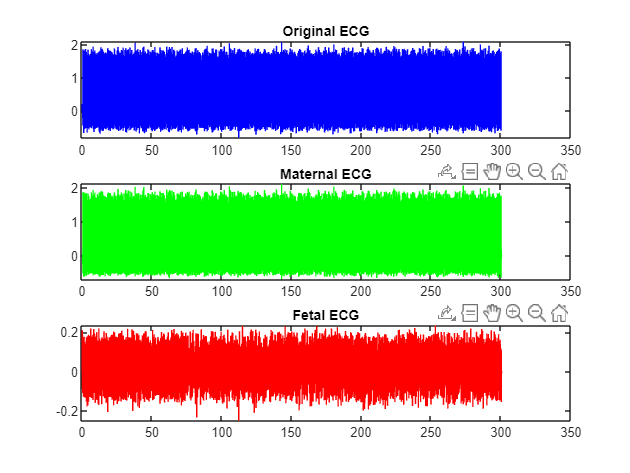

X_raw = [sig1 sig2 sig3 sig4];

% 1. Preprocessing

X_im=FecgImpArtCanc(X_raw,fs); % Impulse artefact cancellation
templateSize = 20;
windowTime=0.049;
count=1;

% Perform cancellation without smoothing for comparison
%{
[fecg1, ~, ~] = cancelMecgAverage(X_im(:,1), fs, templateSize,1,0);
[fecg2, ~, ~] = cancelMecgAverage(X_im(:,2), fs, templateSize);
[fecg3, ~, ~] = cancelMecgAverage(X_im(:,3), fs, templateSize);
[fecg4, ~, delayValue] = cancelMecgAverage(X_im(:,4), fs, templateSize);
%}

[fecg1, ~, ~] = cancelMecg(X_im(:,1), fs, templateSize,0,0);
[fecg2, ~, ~] = cancelMecg(X_im(:,2), fs, templateSize);
[fecg3, ~, ~] = cancelMecg(X_im(:,3), fs, templateSize);
[fecg4, ~, delayValue] = cancelMecg(X_im(:,4), fs, templateSize,0,1);


%{
[fecg1, ~, ~] = cancelMecgTrial(X_im(:,1), fs, templateSize,windowTime);
[fecg2, ~, ~] = cancelMecgTrial(X_im(:,2), fs, templateSize,windowTime);
[fecg3, ~, ~] = cancelMecgTrial(X_im(:,3), fs, templateSize,windowTime);
[fecg4, ~, delayValue] = cancelMecgTrial(X_im(:,4), fs, templateSize,windowTime,0,1);
%}

% 3. ICA/Post-processing
X_fecg = [fecg1, fecg2, fecg3, fecg4];
X_fecg = transpose(X_fecg);
r = 4;
[X_ica, ~, ~, ~] = fastICA(X_fecg,r);

***** Fast ICA (kurtosis) *****
Iter 001: max(1 - |<w001, w000>|) = 0.6627
Iter 002: max(1 - |<w002, w001>|) = 0.0147
Iter 003: max(1 - |<w003, w002>|) = 0.01494
Iter 004: max(1 - |<w004, w003>|) = 0.01047
Iter 005: max(1 - |<w005, w004>|) = 0.01178
Iter 006: max(1 - |<w006, w005>|) = 0.01237
Iter 007: max(1 - |<w007, w006>|) = 0.005899
Iter 008: max(1 - |<w008, w007>|) = 0.0007094
Iter 009: max(1 - |<w009, w008>|) = 7.632e-05
Iter 010: max(1 - |<w010, w009>|) = 2.129e-05
Iter 011: max(1 - |<w011, w010>|) = 9.104e-06
Iter 012: max(1 - |<w012, w011>|) = 4.21e-06
Iter 013: max(1 - |<w013, w012>|) = 2e-06
Iter 014: max(1 - |<w014, w013>|) = 9.498e-07



X_ica = transpose(X_ica);
X_fecg = transpose(X_fecg);
comparedSignal = fecg4;
[f1, estimatedR] = compareDirectTrial(comparedSignal, directImpulse,delayValue,fs);
f1=f1

f1 = 0.0844

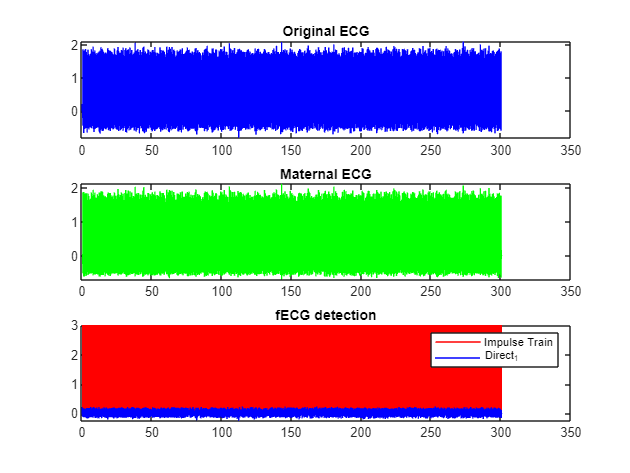

plotTime =(0:length(fecg4)-1)*1/fs;
plot(plotTime,3*estimatedR(1:length(fecg4)),LineWidth=1, Color='red')
hold on
plot(plotTime,fecg4,Color='blue');
title('fECG detection')
legend({'Impulse Train', 'Direct_1'});
hold off

%{
qrsM=chanelSelection(X_im,fs);
Xr=FecgQRSmCanc(X_im,qrsM,fs,'Name');
plot(Xr(:,1))
%}

%{
sig1=fecg1;
n = length(sig1);
[qrs_amp_raw,qrs_i_raw,~] = pan_tompkin(sig1,fs,0); % find R-peak locations
impulseTrain =  zeros([1 n]);
Rpeaks = length(qrs_i_raw);
for i=1:Rpeaks
   impulseTrain(qrs_i_raw(i)) = 1; % indicate locations of R-peaks
end

if(1) % Plot impulse train of detected R-peaks vs. raw signal
    plotTime =(0:length(sig1)-1)*1/fs;
    plot(plotTime,3*impulseTrain(1:length(sig1)),LineWidth=1, Color='red')
    hold on
    plot(plotTime,sig1,Color='blue');
    title('MECG')
    legend({'Impulse Train', 'Direct_1'});
    hold off
    
end

%{
subplot(2,1,1);
plot(sig1)
title('fecg1')

subplot(2,1,2);
plot(sig2)
title('fecg2')
%}

compareTrial(sig2,sig1,fs)
%}